**1) Let's assume y = 0.5e^(0.1x) + 2        Let's plot this function from x = 0 to 40**

xx = 0:1:20

xx =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


yy = 5.*exp(0.25.*xx)

yy =     5.0000    6.4201    8.2436   10.5850   13.5914   17.4517   22.4084   28.7730   36.9453   47.4387   60.9125   78.2132  100.4277  128.9517  165.5773  212.6054  272.9908  350.5271  450.0857  577.9214  742.0658


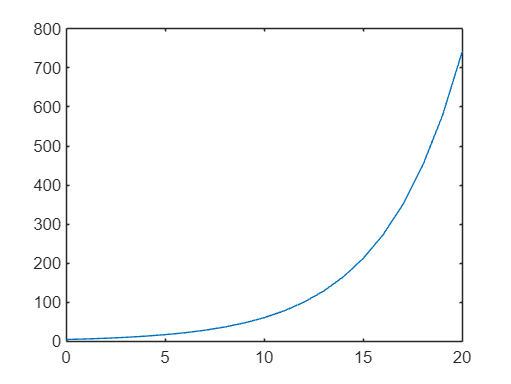

plot(xx,yy,'-')

xtest = 12.5

xtest = 12.5000

yt = 5.*exp(0.25.*xtest)

yt = 113.7995

 **2) Now let's assume that we don't know this function, but we know only some points on this function. **

**For example, if we only know 2 points with equal interval between 0 and 40, then we can use linear interpolation to predict the unknown function**

x = linspace(0,20,3)

x =      0    10    20


y = 5.*exp(0.25.*x)

y =     5.0000   60.9125  742.0658



p1 = polyfit(x,y,2)

p1 =     3.1262  -25.6708    5.0000


yy1 = polyval(p1,xx)

yy1 =     5.0000  -17.5446  -33.8368  -43.8765  -47.6639  -45.1989  -36.4814  -21.5116   -0.2893   27.1854   60.9125  100.8920  147.1239  199.6082  258.3449  323.3340  394.5756  472.0695  555.8159  645.8146  742.0658


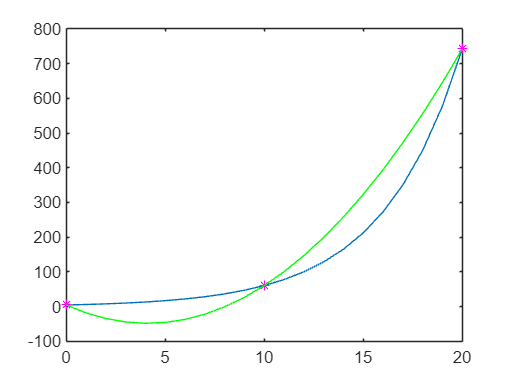

plot(xx,yy,'-')
hold on
plot(x,y,'*m')
hold on
plot(xx,yy1,'-g')
hold off

yp = polyval(p1,xtest)

yp = 172.5845

er = abs(yt-yp)/yt

er = 0.5166

er = er *100

er = 51.6566

**3) Now assume that we only know 3 points with equal interval between 0 and 40, then we can use quadratic interpolation to predict the unknown function**

x = linspace(0,40,3)

x =      0    20    40


y = 0.5.*exp(0.1.*x)+2

y =     2.5000    5.6945   29.2991



p1 = polyfit(x,y,2)

p1 =     0.0255   -0.3505    2.5000


yy1 = polyval(p1,xx)

yy1 =     2.5000    2.1750    1.9010    1.6780    1.5061    1.3852    1.3153    1.2964    1.3286    1.4118    1.5460    1.7313    1.9675    2.2548    2.5931    2.9825    3.4228    3.9142    4.4566    5.0501    5.6945


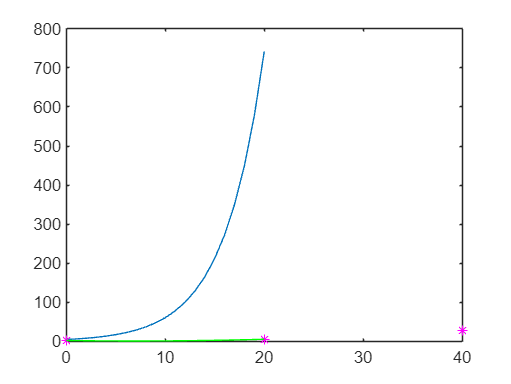


plot(xx,yy,'-')
hold on
plot(x,y,'*m')
hold on
plot(xx,yy1,'-g')
hold off

xtest = 15

xtest = 15

yp = polyval(p1,xtest)

yp = 2.9825

**4) Now assume that we only know 4 points with equal interval between 0 and 40, then we can use cubic interpolation to predict the unknown function**

x = linspace(0,40,4)

x =          0   13.3333   26.6667   40.0000


y = 0.5.*exp(0.1.*x)+2

y =     2.5000    3.8968    9.1960   29.2991



p1 = polyfit(x,y,3)

p1 =     0.0008   -0.0197    0.2310    2.5000


yy1 = polyval(p1,xx)

yy1 =     2.5000    2.7120    2.8893    3.0364    3.1580    3.2585    3.3427    3.4151    3.4803    3.5430    3.6076    3.6789    3.7614    3.8597    3.9785    4.1222    4.2956    4.5032    4.7496    5.0394    5.3773


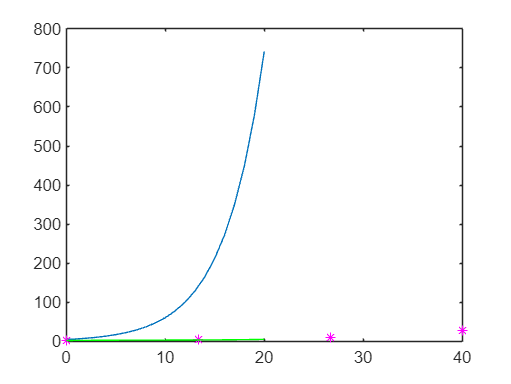


plot(xx,yy,'-')
hold on
plot(x,y,'*m')
hold on
plot(xx,yy1,'-g')
hold off

xtest = 15

xtest = 15

yp = polyval(p1,xtest)

yp = 4.1222